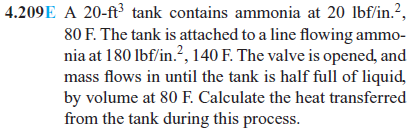

# given

u = symunit;
Vtank = 20*u.ft^3;

# tank (state 1)

% ------------------------
p1 = 20*u.psi;
T1 = 80*u.Fahrenheit;
v1 = 16.7651*u.ft^3/u.lbm;
h1 = 657.02*u.Btu/u.lbm;
u1 = rewrite(h1-p1*v1, [u.Btu u.lbm]);
% ------------------------
m1 = Vtank/v1;
% ------------------------

# tank (state 2)

% -------------------------
p2 = 153.116*u.psi;
T2 = 80*u.Fahrenheit;
vf2 = 0.02668*u.ft^3/u.lbm;
vg2 = 1.9526*u.ft^3/u.lbm;
uf2 = 130.92*u.Btu/u.lbm;
ug2 = 574.30*u.Btu/u.lbm;
% -------------------------
Vf2 = 0.50*Vtank;
Vg2 = 0.50*Vtank;
mf2 = Vf2/vf2;
mg2 = Vg2/vg2;
m2 = mf2+mg2;
% ------------------------
v2 = Vtank/m2;
U2 = mf2*uf2+mg2*ug2;
% ------------------------

# inflow properties

pi = 180*u.psi;
Ti = 140*u.Fahrenheit;
vi = interp1([175 200], [1.9708 1.6984], double(removeUnits(pi)))*u.ft^3/u.lbm;
hi = interp1([175 200], [667.67 663.90], double(removeUnits(pi)))*u.Btu/u.lbm;

# exit properites

me = 0;
he = 0;

# conservation of mass

syms mi;
mi = solve(m2-m1 == mi-me);

# conservation of energy

syms Qcv;
Qcv = solve(U2-m1*u1 == Qcv+mi*hi-me*he);
Qcv_vpa = vpa(Qcv, 8) %#ok

$$Qcv\_vpa = -201286.55\,{\mathrm{Btu}}_{\mathrm{IT}}$$

clear Qcv_vpa;